wp=0.2*pi; ws = 0.3*pi;
M = input('Enter order of filter: ');
pass = fix(wp*M/(2*pi)) + 1;
stop = fix(ws*M/(2*pi)) + 1;
trans = stop - pass;
if rem(M, 2) == 0, U = M/2 - 1; 
else 
    U = (M-1)/2;
end
if trans == 1
    Hr = [ones(1, pass) , zeros(1, U - pass +1)];
else
    tk = pass +1: stop;
    transmag = 0.5 * (1 + cos(pi* (tk - pass)/ trans));
    Hr = [ones(1, pass), transmag, zeros(1, U - stop +1)]
end

Hr =     1.0000    1.0000    1.0000    1.0000    1.0000    0.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


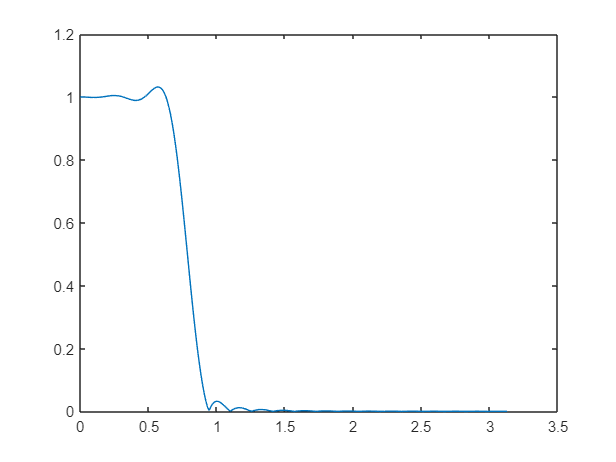

k = 0 : U;
G= (-1).^k.*Hr;
if rem(M, 2) == 0
    GM = [G 0 -G(U+1:-1:2)];
else
    GM = [G -G(U+1:-1:2)];
end
I = 0: M-1;
H = GM.*exp(pi*I*1i/M);
h = ifft(H);
mag = abs(fft(h,512));
w = (0:255) * pi/256;
plot(w, mag(1:256));

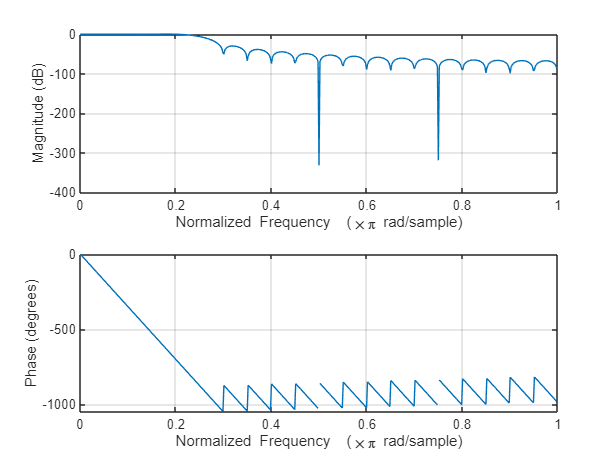

figure,
freqz(h, 1 ,512)